clear; clc; close all;

syms n z real
a  = 2;                  % base da exponencial (ajuste conforme o problema)
x_n = ((a)^n)*a;                 % x[n], valido para n >= 0 (multiplicado por u[n])

%% 2) TRANSFORMADA Z SIMBOLICA
X_z = ztrans(x_n, n, z);
X_z = simplify(X_z);

disp('Sinal x[n]:');

Sinal x[n]:


x_n

$$x\_n = 2\,2^{n}$$

disp('Transformada Z X(z):');

Transformada Z X(z):


X_z

$$X\_z = \frac{2\,z}{z-2}$$



%% 3) POLOS E ZEROS DE X(z)
[numS, denS] = numden(X_z);          % separa numerador/denominador simbolicos
num = sym2poly(expand(numS));
den = sym2poly(expand(denS));

zeros_X = roots(num);
polos_X = roots(den);

fprintf('\nZeros de X(z):\n');   disp(zeros_X)


Zeros de X(z):
     0



fprintf('Polos de X(z):\n');     disp(polos_X)

Polos de X(z):
     2




raio_rdc = max(abs(polos_X));
fprintf('RDC (sinal causal): |z| > %.4f\n', raio_rdc);

RDC (sinal causal): |z| > 2.0000


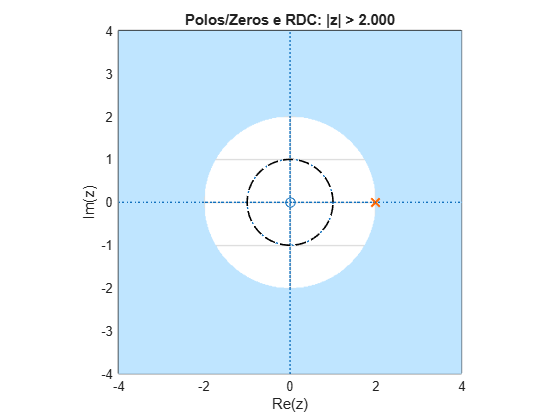


%% 4) DIAGRAMA DE POLOS, ZEROS E RDC (2D)
figure('Name','Polos, Zeros e RDC (2D)');
zplane(num, den);
hold on;


%% 5) CUSTOMIZAÇÃO DO DIAGRAMA DE POLOS, ZEROS E RDC (2D) (IA)
theta = linspace(0, 2*pi, 300);
plot(cos(theta), sin(theta), 'k--', 'LineWidth', 1);   % circulo unitario (referencia)

r_max = max(2, raio_rdc*2);
[Xg, Yg] = meshgrid(linspace(-r_max, r_max, 400));
Rg = sqrt(Xg.^2 + Yg.^2);
rdc_mask = double(Rg > raio_rdc);       % 1 dentro da RDC, 0 fora

contourf(Xg, Yg, rdc_mask, [0.5 0.5], 'LineColor', 'none');
colormap([1 1 1; 0.75 0.9 1]);          % branco fora / azul claro na RDC
alpha(0.35);

[hz, hp, ht] = zplane(num, den);        % redesenha polos/zeros por cima da regiao
% hz = handle dos zeros | hp = handle dos polos | ht = handle do circulo unitario

% Customizacao de cor do polo (troque a cor como quiser):
set(hp, 'Color', [1 0.4 0], 'MarkerFaceColor', [1 0.4 0], 'LineWidth', 1.5, 'MarkerSize', 9);
% Se quiser mudar tambem os zeros:
% set(hz, 'Color', [0 0.6 0], 'LineWidth', 1.5, 'MarkerSize', 9);

plot(cos(theta), sin(theta), 'k--', 'LineWidth', 1.2);
title(sprintf('Polos/Zeros e RDC: |z| > %.3f', raio_rdc));
xlabel('Re(z)'); ylabel('Im(z)');
grid on; axis equal;
xlim([-r_max r_max]); ylim([-r_max r_max]);   % trava a escala (depois do axis equal!)
set(gca, 'XLimMode', 'manual', 'YLimMode', 'manual');
hold off;

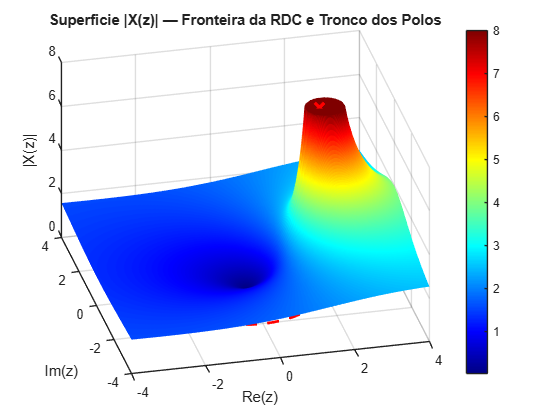


%% 6) |X(z)| EM 3D SOBRE O PLANO z, COM A RDC DESTACADA
n_pts = 350; 
[ReZ, ImZ] = meshgrid(linspace(-r_max, r_max, n_pts));
Zg = ReZ + 1i*ImZ;
 
Xnum = polyval(num, Zg);
Xden = polyval(den, Zg);
modX = abs(Xnum ./ Xden);
 
% Define um teto de amplitude fixo para saturar o pico e evitar a divergencia infinita
teto_visual = 8; 
modX(modX > teto_visual) = teto_visual;

figure('Name','|X(z)| em 3D e RDC');
surf(ReZ, ImZ, modX, 'EdgeColor', 'none');
hold on;
 
% Desenha a borda da RDC no plano z = 0 e tambem projetada na superficie
z_circ = raio_rdc * exp(1i*theta);
plot3(real(z_circ), imag(z_circ), zeros(size(theta)), 'r--', 'LineWidth', 2);

% Plota as posicoes exatas dos polos no topo do corte
mod_polos = polyval(num, polos_X) ./ polyval(den, polos_X); % Apenas para referência
plot3(real(polos_X), imag(polos_X), repmat(teto_visual, size(polos_X)), 'rx', 'MarkerSize', 10, 'LineWidth', 2.5);

colormap(jet); colorbar;
xlabel('Re(z)'); ylabel('Im(z)'); zlabel('|X(z)|');
title('Superficie |X(z)| — Fronteira da RDC e Tronco dos Polos');
view(-37.5, 30); % Angulo de visao otimizado para enxergar os picos e a base
grid on; axis tight;
hold off;